clear all;
A = [2 3;
    -1 4];
B = [0;
    1];
C = [1 0];
D = 0;
sys = ss(A,B,C,D);

zeta = 0.8;
w_n = 10;

rank(obsv(sys))

ans = 2


poly = [1 2*zeta*w_n w_n^2];
root = roots(poly)

root =   -8.0000 + 6.0000i
  -8.0000 - 6.0000i



L = place(A',C',root)'

L =    22.0000
   59.0000


error1 = ss(A-L*C, [0; 0], [1 0], 0);
error2 = ss(A-L*C, [0; 0], [0 1], 0);
t = 0:0.01:2;
u = zeros(size(t));
e0 = [1, -2] % 초기값

e0 =      1    -2


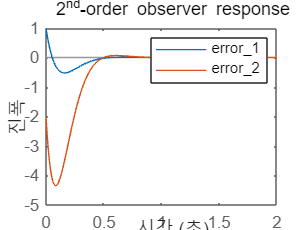

lsim(error1,u,t,e0);
hold on;
lsim(error2,u,t,e0);
hold off;
title('2^{nd}-order observer response');
legend('error_1','error_2');

clearvars;
A = [2 3;
    -1 4];
B = [0;
    1];
C = [1 0];
D = 0;  
sys = ss(A,B,C,D);

zeta = 0.8;
w_n = 10;

poly = [1 2*zeta*w_n w_n^2];
root = roots(poly)

root =   -8.0000 + 6.0000i
  -8.0000 - 6.0000i



K = place(A, B, root)

K =    44.3333   22.0000


L = place(A', C', root)'

L =    22.0000
   59.0000


At = [A-B*K B*K;
    zeros(size(A)) A-L*C]

At =     2.0000    3.0000         0         0
  -45.3333  -18.0000   44.3333   22.0000
         0         0  -20.0000    3.0000
         0         0  -60.0000    4.0000


Bt = [zeros(size(B));
    zeros(size(B))]

Bt =      0
     0
     0
     0


Ct = [C zeros(size(C))]

Ct =      1     0     0     0



t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u = zeros(size(t))

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x0 = [0.01 0]

x0 =     0.0100         0


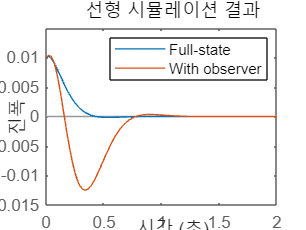


sys1 = ss(A-B*K, B, C, D);
lsim(sys1, u, t, x0);
hold on;

sys2 = ss(At, Bt, Ct, D);
lsim(sys2, zeros(size(t)), t, [x0 x0]);
legend('Full-state', 'With observer');
hold off;

% inverted pendulum model
clearvars;
A = [0 1 0 0;
    0 0 -1 0;
    0 0 0 1;
    0 0 100 0];
B = [0;
    0.1;
    0;
    1];
C = [1 0 0 0];
D = 0;

rank(ctrb(A,B))

ans = 4

rank(obsv(A,C))

ans = 4


zeta = 0.8;
w_n = 0.5;
poly1 = [1 2*zeta*w_n w_n^2];
r1r2 = roots(poly1)

r1r2 =   -0.4000 + 0.3000i
  -0.4000 - 0.3000i


r1 = r1r2(1);
r2 = r1r2(2);
r3 = r1*20; %minor poles
r4 = r2*20;

p1 = [r1; r2; r3; r4]

p1 =   -0.4000 + 0.3000i
  -0.4000 - 0.3000i
  -8.0000 + 6.0000i
  -8.0000 - 6.0000i


K = place(A,B,p1)

K =    -2.2727   -7.6364  213.2773   17.5636



% 옵저버 같은 경우 퍼포먼스가 큰 의미는 없고 빨리 수렴하고 컨트롤이 되기만 하면 됨
% 우리가 r3,r4를 감쇄가 빠른 값을 골라줬으므로 그것을 기반으로 적당히 4개 pole을 결정
p2 = [r3; r4; r3*2; r4*2]

p2 =   -8.0000 + 6.0000i
  -8.0000 - 6.0000i
 -16.0000 +12.0000i
 -16.0000 -12.0000i


L = place(A',C',p2)'

L = 1.0e+05 *

    0.0005
    0.0111
   -0.1440
   -1.5120


% Connect the conpensator and simulate
C_new = [0 0 1 0] % to see pendulum angle

C_new =      0     0     1     0


At = [A-B*K B*K; zeros(size(A)) A-L*C];
Bt = [zeros(size(B));
    zeros(size(B))];
Ct = [C_new zeros(size(C_new))];

t = 0:0.01:5;
u = zeros(size(t));
x0 = [0 0 5.72*pi/180 0] %초기값

x0 =          0         0    0.0998         0


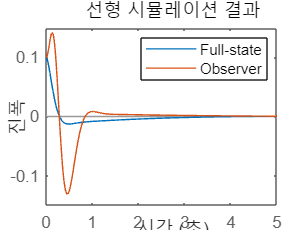


sys1 = ss(A-B*K, B, C_new, D);
lsim(sys1, u, t, x0);
hold on;

sys2 = ss(At, Bt, Ct, D);
lsim(sys2, u, t, [x0 x0]); %초기 obsever 가 0으로 세팅, 초기 에러 = x0-0 = x0
legend('Full-state', 'Observer');
hold off;

% Reference input
At = [A-B*K B*K; zeros(size(A)) A-L*C];
Bt = [B;
    zeros(size(B))];
Ct = [C zeros(size(C))]; % pendulem position을 보기 위해
sys2 = ss(At,Bt,Ct,0);

% N 찾기
sys2tf = tf(sys2)

sys2tf =
 
       0.1 s^2 + 7.105e-16 s - 11
  ------------------------------------
  s^4 + 16.8 s^3 + 113 s^2 + 84 s + 25
 
연속시간 전달 함수입니다.
모델 속성


gain = dcgain(sys2tf)

gain = -0.4400

N = 1/gain

N = -2.2727

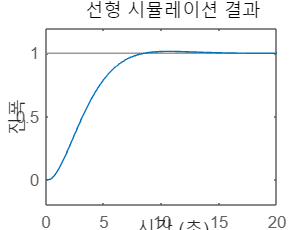

Bt = [N*B;
    zeros(size(B))];
sys2 = ss(At,Bt,Ct,0);

t = 0:0.1:20;
u = ones(size(t)); % unit step input
x0 = [0 0 0 0];
lsim(sys2, u, t, [x0 x0]);